# The calculation of sample capacitance

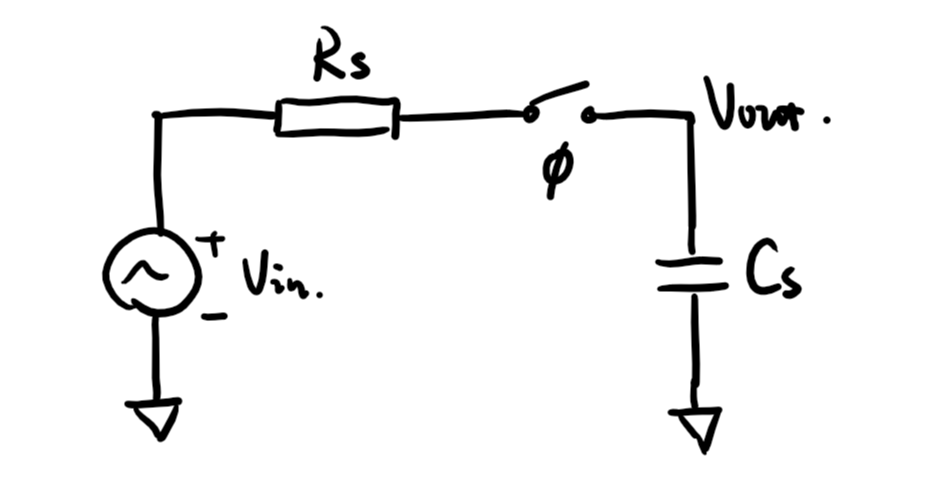

采样的热噪声是决定ADC信噪比的决定性因素，基于以上的采样模型，输出噪声的有效值为：


$$V_{\textrm{out},\textrm{rms}} =\sqrt{\;\left(\frac{k_b T}{C_s }\right)},\textrm{where}\;k_b =1\ldotp 38\times {10}^{-23} \;J/K\;$$


% Clean the previous workspace
clear; clc;


VDD = 3.3;          % Supply voltage
Vref = 3.3;         % Reference voltage
kb = 1.38E-23;      % Boltzmann constant
T = 300;            % Kelvin temperature
N = 17;             % Number of resolution (without sign bit)
N_SUB = 5;          % Number of resolution (sub ADC)


## Cap sweep

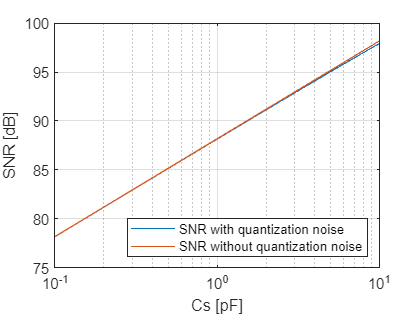

Vin_rms = VDD / sqrt(2);
LSB = VDD / 2^N;
Vn_quan_rms = LSB / sqrt(12);       % quantization noise
c = linspace(0.1,10) * (1E-12);
Vn_ther_rms = sqrt(kb*T./c);        % thermal noise

SNR_quan = Vin_rms^2 ./ (Vn_quan_rms^2 + 2*Vn_ther_rms.^2);
SNR_ther = Vin_rms^2 ./ ( 2*Vn_ther_rms.^2);

figure
semilogx(c./(1E-12), mag2db(SNR_quan) / 2);
hold on;
semilogx(c./(1E-12), mag2db(SNR_ther) / 2);
grid on;
box on;
xlabel("Cs [pF]");
ylabel("SNR [dB]");
legend(["SNR with quantization noise", "SNR without quantization noise"],...
    "Location","southeast");

## Cap Selection

SNR_Target_db = 86

SNR_Target_db = 86

SNR_Target = db2mag(SNR_Target_db*2);
Vn_out = (Vin_rms^2) / SNR_Target;

% with quantization noise
Cs_wi_quan = 2*kb*T / (Vn_out - Vn_quan_rms^2)

Cs_wi_quan = 6.0773e-13


% without quantization noise
Cs_wo_quan =  2*kb*T / (Vn_out)

Cs_wo_quan = 6.0539e-13

## Cap Mismatch

% parameters of MIM caps
c0 = 9.69*10^-4;
mr = 1;
ac0 = 3.16*10^-16;

lr = 16*10^-6;
wr = 16*10^-6;
Cunit = c0*(lr*wr*mr) * (1E12)              % Unit: pF

Cunit = 0.2481

Ctot = Cunit * 2^N_SUB                      % Unit: pF

Ctot = 7.9380

geo_fac=1/(lr*wr*mr);
dc0_mis = ac0*geo_fac;

std_C_unit = dc0_mis/c0                     % single

std_C_unit = 0.0013

std_C_unit_eq = std_C_unit/(2^0.5)          % differential

std_C_unit_eq = 9.0076e-04

% with capacitance mismatch calibration
% INL_code_std = 1/2^N_SUB*( ((2^N_SUB-1)/2^N_SUB)^2 + 1/(2^N_SUB)^2 )^0.5 * std_C_unit_eq *3
INL_code_std = 1 / 2^N_SUB * sqrt((2^N_SUB-1)/(2^N_SUB)) * std_C_unit_eq * 3    % Unit: ppm

INL_code_std = 8.3116e-05

INL_code_max = INL_code_std * Vref / LSB /2                                     % Unit: LSB

INL_code_max = 5.4471